% cd('/Users/platel/Desktop/exp/analysis/');
numanalysis=length(matfile);
pathsave='/Users/platel/Desktop/exp/analysis/origi/';
% folder = cell(0, 0);
assembly = cell(0, 0);

for n =1:numanalysis
    path=cell2mat(matfile(n));
    load (path,'assemblyortho','assemblystat','assemblyraw','sCl','NCell','sClrnd');
    assembly_ortho_repro{n,:}=assemblyortho;
    assembly_stat_repro{n,:}=assemblystat;
    assembly_raw_repro{n,:}=assemblyraw;  
    sil_clust_repro{n,:}=sCl;
    NCell_repro{n,:}=NCell;
    sClrnd_repro{n,:}=sClrnd;
    % folder  = uigetdir('Select a folder');
    % results=load ([folder '/results.mat'],'assemblyortho');
    % assembly{n} =analysis{1,n}.assemblyortho;

end

% % test=load ('/Users/platel/Desktop/exp/analysis/23_10_18_00_06_51P2M_444175_221125_plane1_2023_01_09.09-19-40.nwb/results.mat','assemblyortho');
% % assemblyortho1=test.assemblyortho;


%threshold clustering
for n=1:numanalysis
    th(n)=prctile(sClrnd_repro{n,:},95);
end

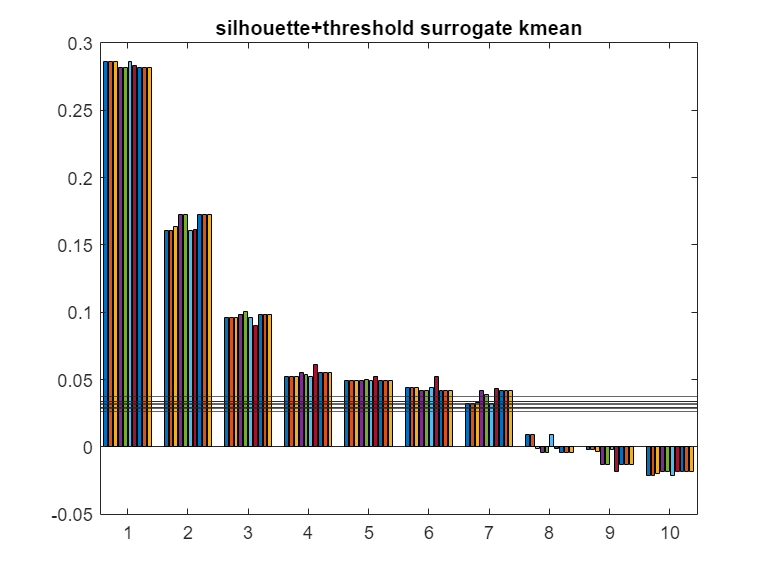

%test silhouette
sCltmp=[];
% for n=1:10
    for i=1:10
        for n=1:numanalysis
            sCltmp(i,n)=sil_clust_repro{n}(i); 
        end
    end
% end
figure
bar(sCltmp)
hold on 
yline(th)
hold off
title('silhouette+threshold surrogate kmean')

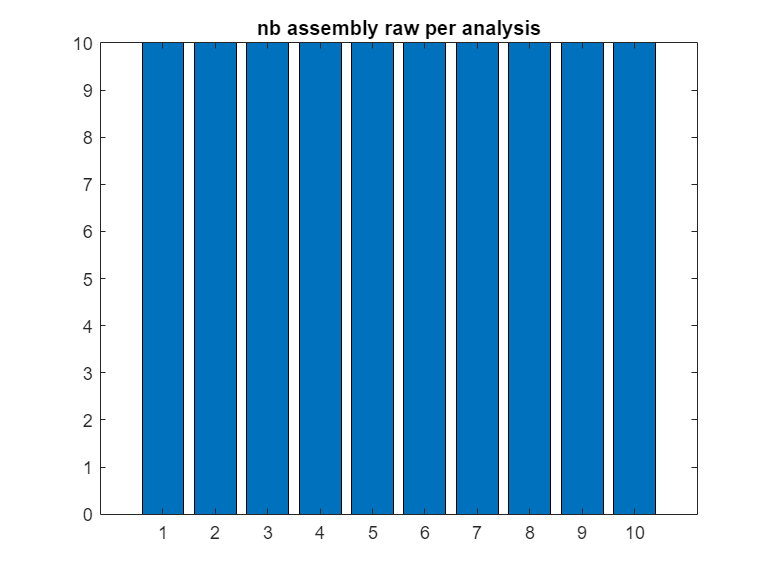

%stat assemblies raw: nb assembly raw per analysis
figure
bar(cellfun(@length,assembly_raw_repro))
title('nb assembly raw per analysis')


mean(cellfun(@length,assembly_raw_repro))

ans = 10

median(cellfun(@length,assembly_raw_repro))

ans = 10

std(cellfun(@length,assembly_raw_repro))

ans = 0

% %stat cells in assemblies
% for i=1 :numel(assembly_raw_repro)
%     total_cell_assembly(i)=sum(cellfun(@length,assembly_raw_repro{i})) ;
% 
% end
% mean(total_cell_assembly)
% median(total_cell_assembly)
% std(total_cell_assembly)

% combinedFigure = figure;
% subplot(1, 2, 1); 
% copyobj(allchild(1), combinedFigure);
% copyobj(allchild(1), combinedFigure);
% copyobj(allchild(2), combinedFigure);
% namegraph=[pathsave 'reproassembly.png'];
% exportgraphics(gcf,namegraph,'Resolution',300);

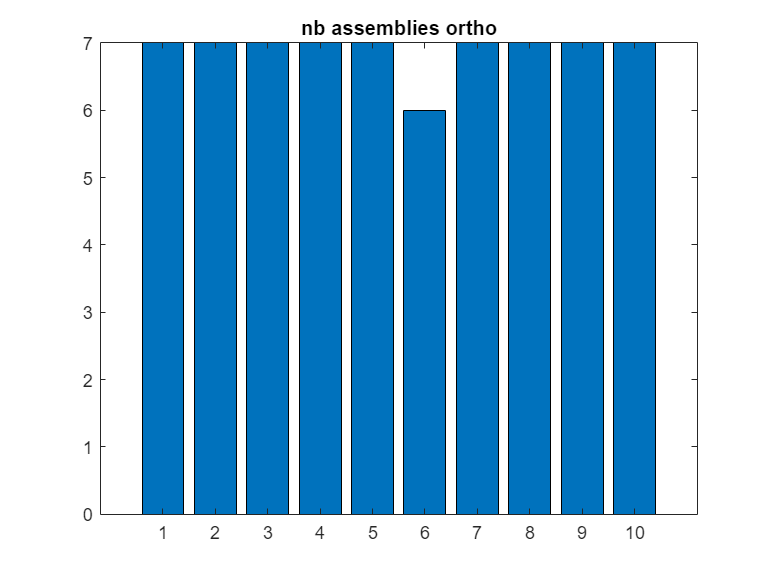

%stat assemblies ortho
figure
bar(cellfun(@length,assembly_ortho_repro))
title('nb assemblies ortho')


mean(cellfun(@length,assembly_ortho_repro))

ans = 6.9000

median(cellfun(@length,assembly_ortho_repro))

ans = 7

std(cellfun(@length,assembly_ortho_repro))

ans = 0.3162

% intersection=[];
% jaccard_similarity=[];
% meanIOU=[];
% sum_intersec=[];
% for i=1:numel(assembly_raw_repro)-1
% 
%     analysis1=assembly{i};
% 
%     for j=i+1:numel(assembly)
% 
%         analysis2=assembly{j};
%         % analysis1=assemblyortho
%         intersection=[];
%         jaccard_similarity=[];
% 
%         for m=1:numel(analysis1)
% 
%             for n=1:numel(analysis2)
% 
%                 intersection(m,n) = numel(intersect(analysis1{m}, analysis2{n}));
%                 union_size = numel(union(analysis1{m}, analysis2{n}));
%                 jaccard_similarity(m,n) = intersection(m,n) / union_size;
% 
%             end
%             % 
%             % figure
%             % bar (jaccard_similarity(m,:))
%             % title(['jacassembly' num2str(m) ])
%             % ylim ([0 1])
%             % % % figure
%             % % %     bar (intersection(m,:)/numel(assemblyortho1{m})*100)
%             %     title(['inter' num2str(m) ])
% 
%         end
%         bestIOU=[];
%         best_inters=[];
%         for m =1: numel(analysis1)
% 
%             bestIOU(m)=max (jaccard_similarity(m,:));
%             best_inters(m)=max (intersection(m,:));
%         end
% 
%         meanIOU(i,j)=mean(bestIOU);
%         sum_intersec(i,j)=sum(best_inters);
%     end
% end
% meanIOUall = meanIOU(meanIOU ~= 0);
% sum_intersecall = sum_intersec(sum_intersec ~= 0);
% mean(meanIOUall)
% std(meanIOUall)
% median(meanIOUall)
% mean (sum_intersecall,'all')
% std(sum_intersecall)


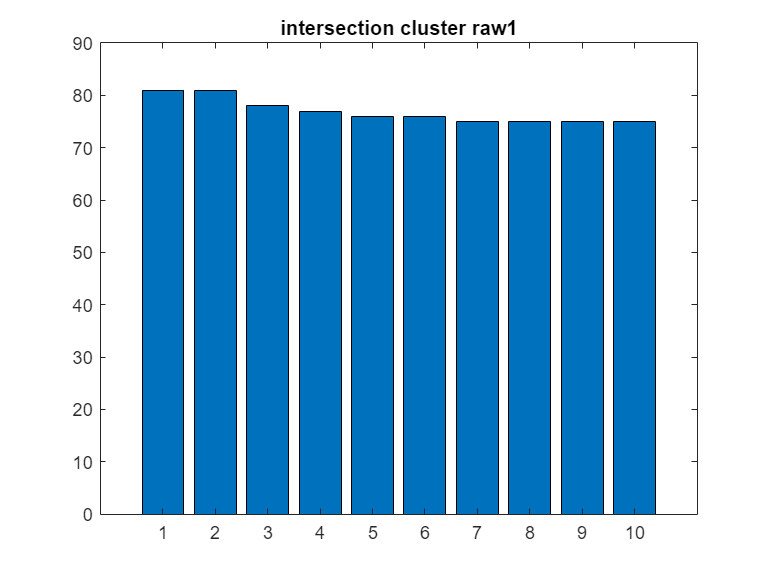

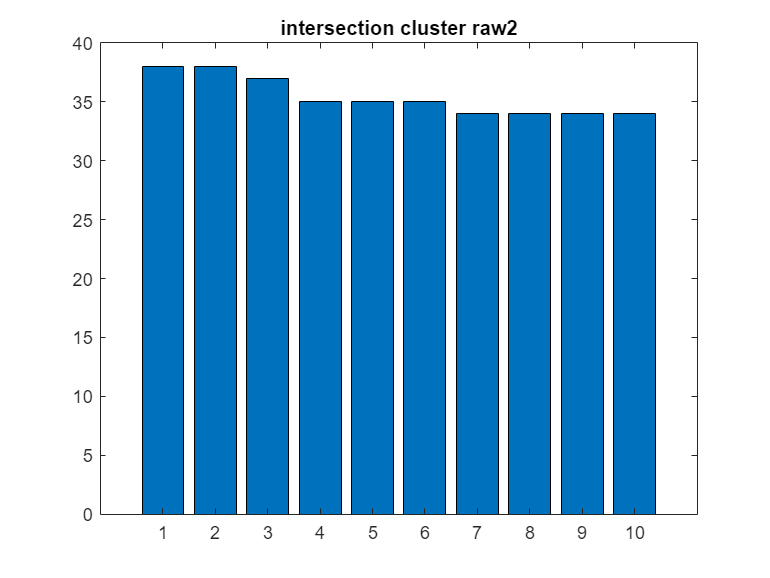

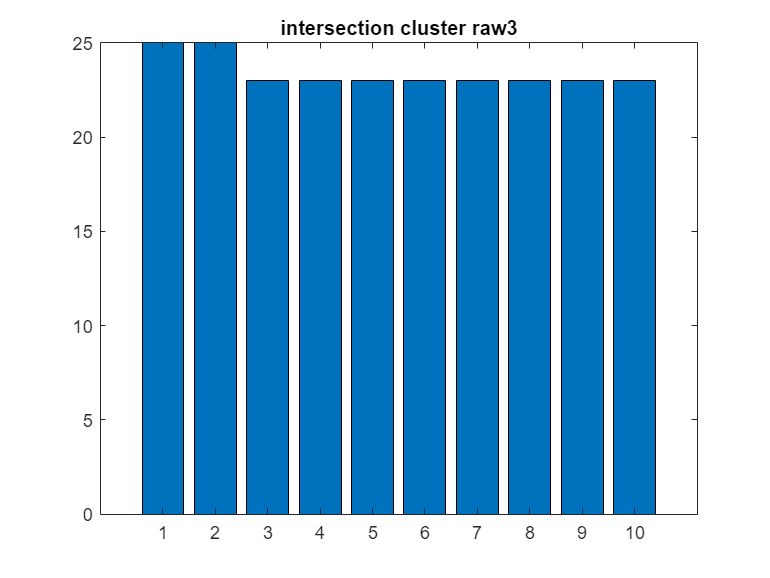

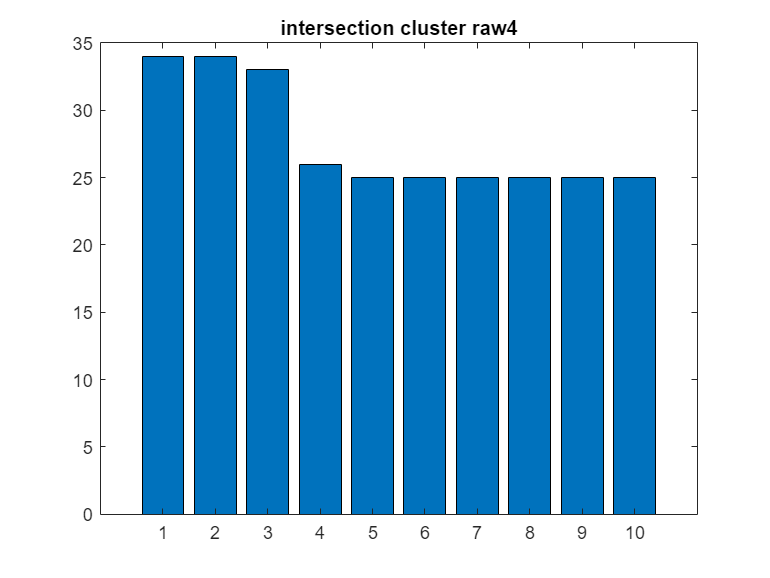

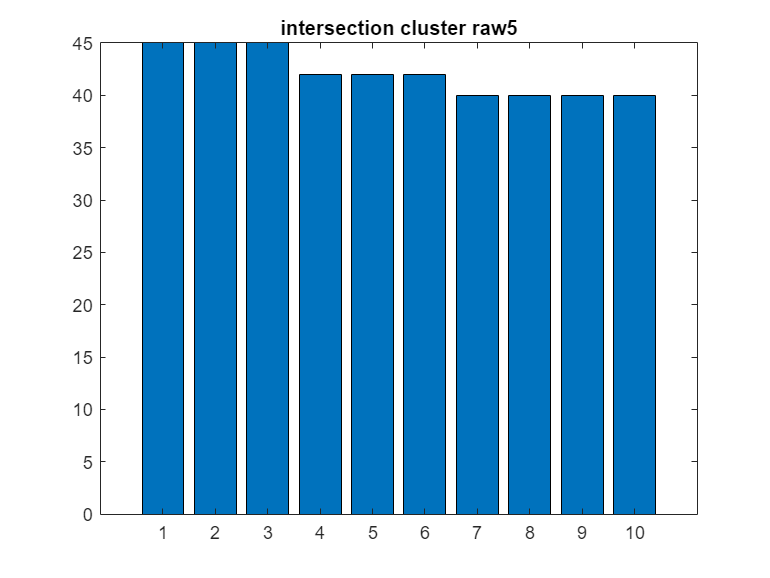

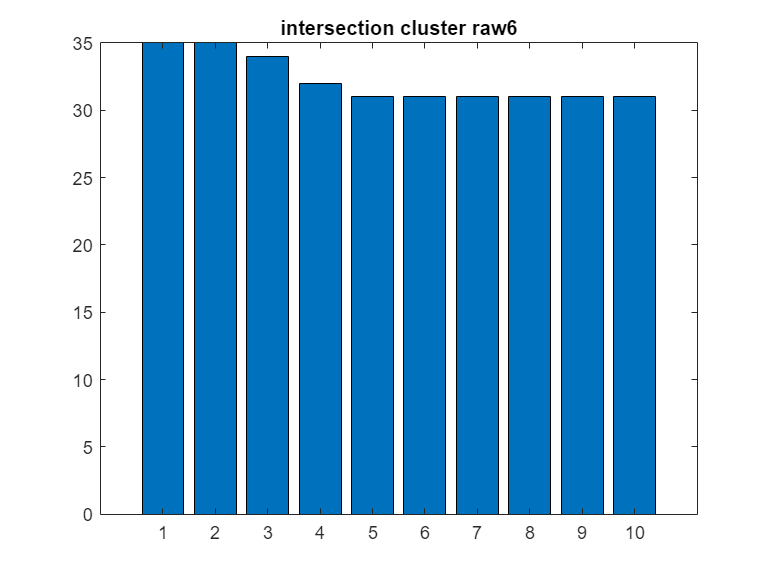

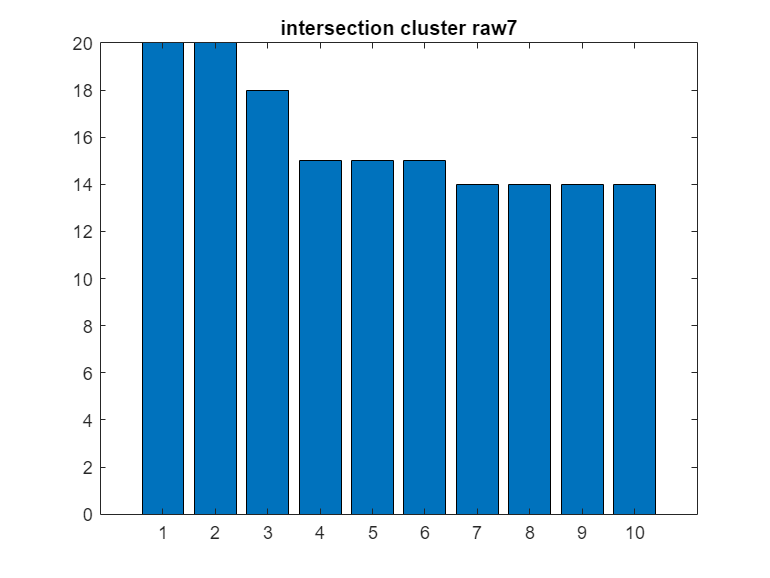

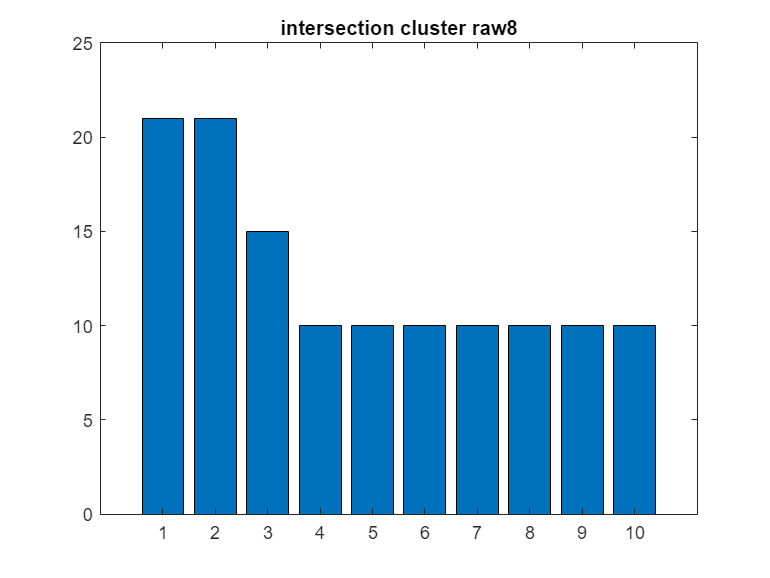

%intersection calculation assembly raw
inter=[];
for cluster=1:length(assembly_raw_repro{1,1})    % on scanne les clusters
    intersection=[];
    intersection = cell2mat(assembly_raw_repro{1}(cluster));%assembly_raw_repro{analyse}(cluster));
    inter(cluster,1)=length(intersection);
    

    for i = 2:numanalysis %on scanne les analyses
        % currentIntersection = intersect(intersection, assembly{i});
        % intersection = intersect(intersection, cell2mat(assembly_raw_repro{i}(2)));
        tmp=[];
        for n=1:length(assembly_raw_repro{i})
            tmp(n)=length(intersect(intersection, cell2mat(assembly_raw_repro{i}(n))));
        end
        [m, idx]=max(tmp);
        intersection = intersect(intersection, cell2mat(assembly_raw_repro{i}(idx)));
        % intersection = intersect(intersection, cell2mat(assembly_raw_repro{i}(2)));
    
        inter(cluster,i)=length(intersection);
        % % Check if the current intersection size is above the threshold
        % if numel(currentIntersection) >= intersectionThreshold
        %     intersection = currentIntersection;
        % end
    end
end

for n=1:length(assembly_raw_repro{1,1}) 
    figure
    bar (inter(n,:))
    title(['intersection cluster raw' num2str(n)])
end

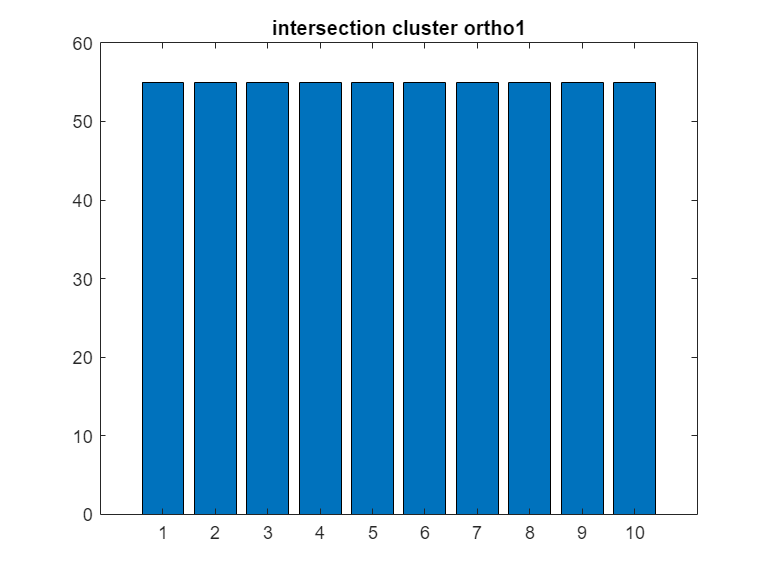

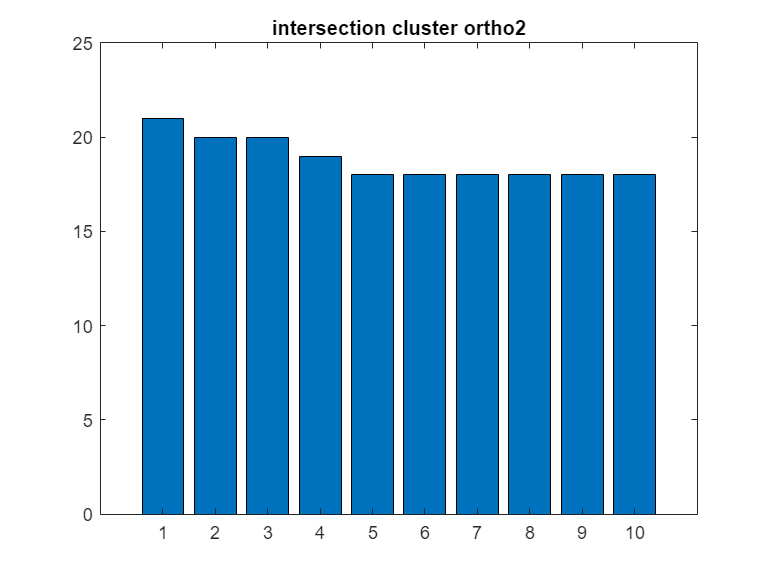

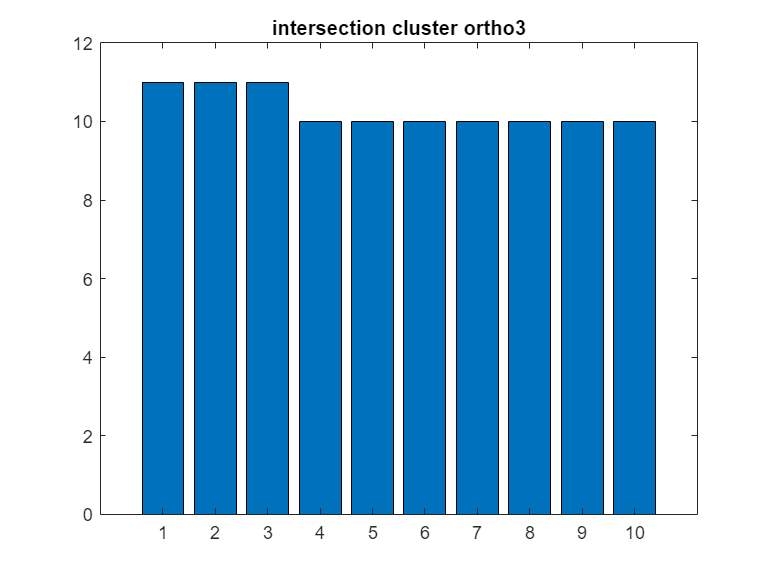

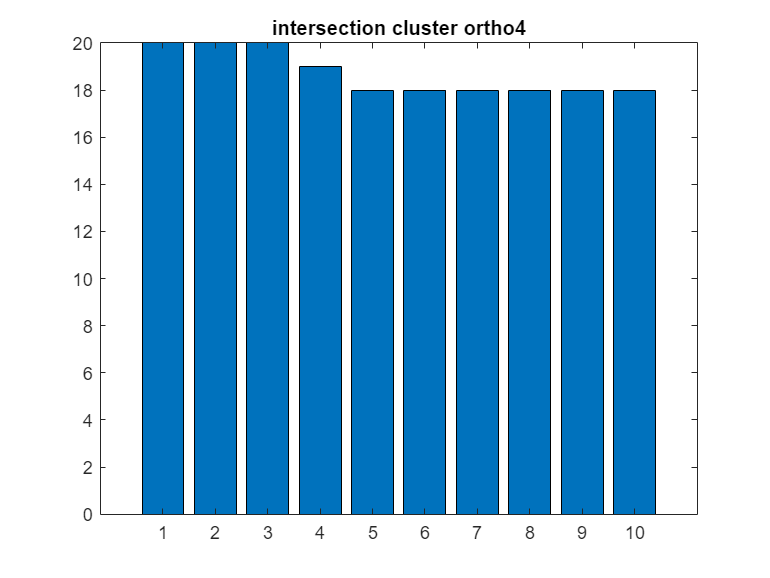

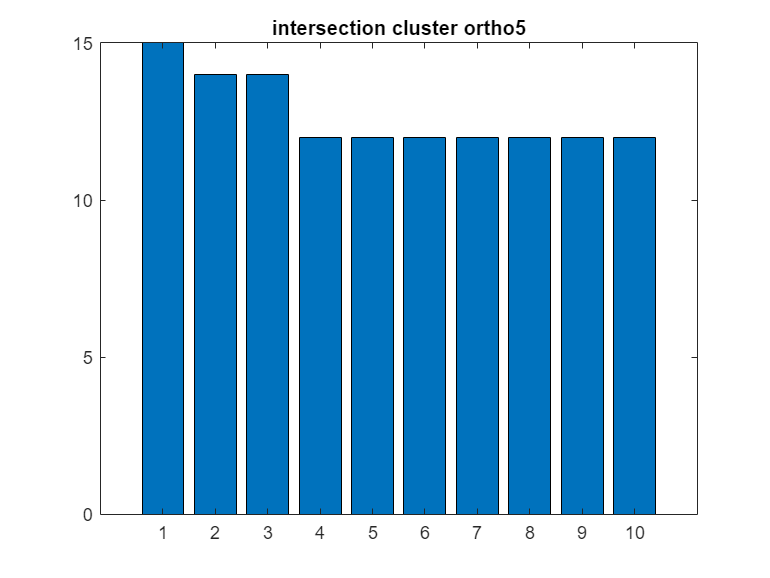

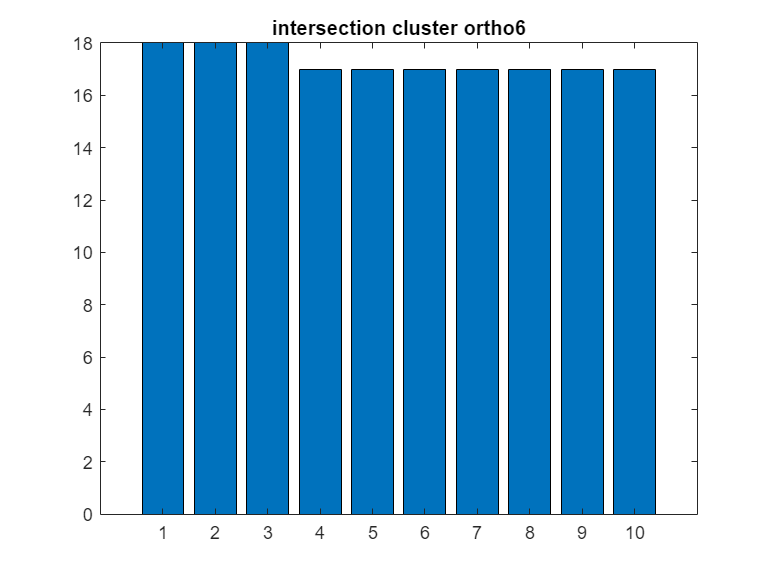

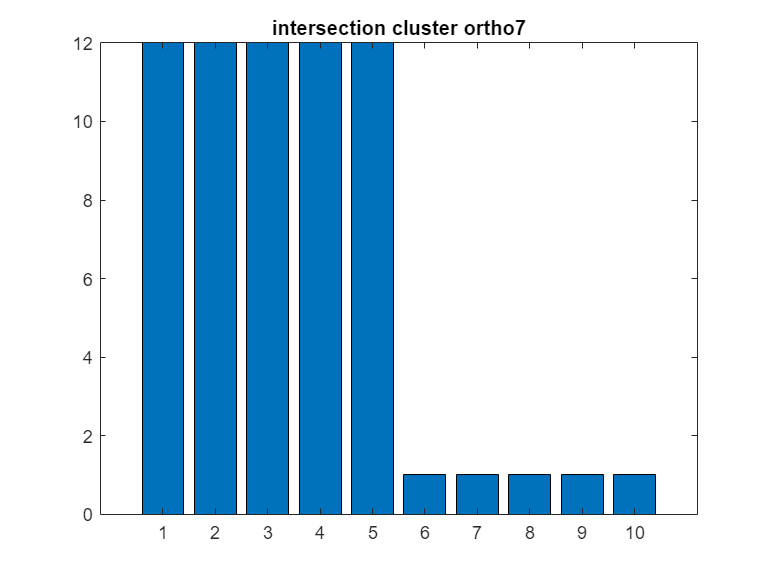

%intersection calculation assembly ortho
inter=[];
for cluster=1:length(assembly_ortho_repro{1,1})   % on scanne les clusters
    intersection=[];
    intersection = cell2mat(assembly_ortho_repro{1}(cluster));%assembly_raw_repro{analyse}(cluster));
    inter(cluster,1)=length(intersection);
    

    for i = 2:numanalysis%:10 %on scanne les analyses
        % currentIntersection = intersect(intersection, assembly{i});
        % intersection = intersect(intersection, cell2mat(assembly_raw_repro{i}(2)));
        tmp=[];
        for n=1:length(assembly_ortho_repro{i})
            tmp(n)=length(intersect(intersection, cell2mat(assembly_ortho_repro{i}(n))));
        end
        [m, idx]=max(tmp);
        intersection = intersect(intersection, cell2mat(assembly_ortho_repro{i}(idx)));
        % intersection = intersect(intersection, cell2mat(assembly_raw_repro{i}(2)));
    
        inter(cluster,i)=length(intersection);
        % % Check if the current intersection size is above the threshold
        % if numel(currentIntersection) >= intersectionThreshold
        %     intersection = currentIntersection;
        % end
    end
end
for n=1:length(assembly_ortho_repro{1,1}) 
    figure
    bar (inter(n,:))
    title(['intersection cluster ortho' num2str(n)])
end

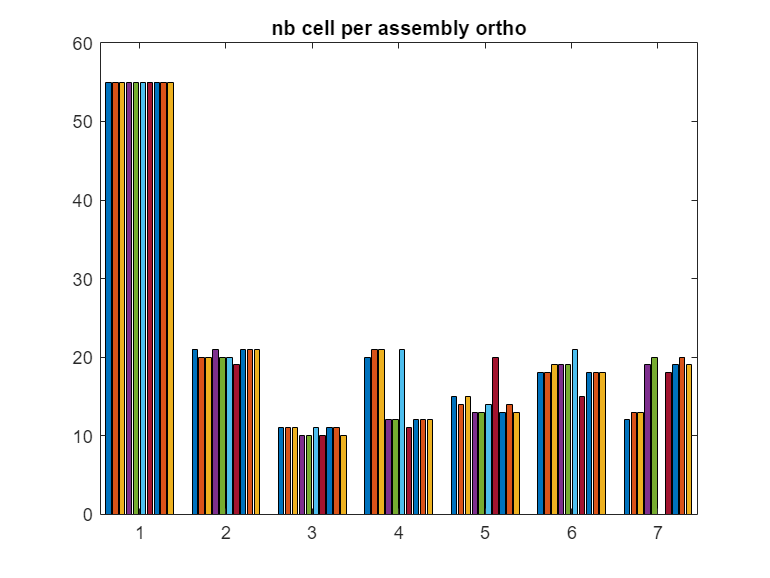

%nb total cell per cluster

maxass=max(cellfun(@length,assembly_ortho_repro));
tmp=zeros(10,maxass);
% test=[4,8,9,10]
for n=1:numanalysis
    nbass=length(cellfun(@length,assembly_ortho_repro{n}));
    tmp(n,1:nbass)=cellfun(@length,assembly_ortho_repro{n});
    
end
% tmp=cell2mat(tmp)
figure
bar (tmp')
title('nb cell per assembly ortho')